% =========================================================================
%  Real test realization
%  Author: Yago Lizarribar
% =========================================================================
clear; clc; close all; warning ('off','all');

% Speed of light
global c; %m/s
c = 299792458;

% adds subfolder with functions to PATH
% [p,n,e] = fileparts(mfilename('fullpath'));
p = pwd;
addpath([p '/tdoa']);
addpath([p '/ltess']);
addpath([p, '/geodesy']);
addpath([p, '/optimization']);

%% Load configuration
filename = 'real_tests/locations_dab_dab.json';
problem_data = json_load(filename);

% Unknown transmitter
fUS = problem_data.transmitters.unknown.freq * 1e6;
sr_local = problem_data.config.sample_rate;
us_lat = problem_data.transmitters.unknown.coord(1);
us_lon = problem_data.transmitters.unknown.coord(2);

% Reference transmitter
fRS = problem_data.transmitters.reference.freq * 1e6;
sr_ltess = problem_data.config.sample_rate_ltess;
rs_lat = problem_data.transmitters.reference.coord(1);
rs_lon = problem_data.transmitters.reference.coord(2);

% Sensors
NUM_SENSORS = length(problem_data.sensors);
NUM_FILES_SENSOR = problem_data.config.files_per_sensor;

folder_location = '/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/data/real_tests';
localization_files = cell(NUM_SENSORS, NUM_FILES_SENSOR);
ltess_files = cell(NUM_SENSORS, NUM_FILES_SENSOR);

sensors = zeros(NUM_SENSORS, 3);
distances_rs = zeros(NUM_SENSORS,1);
distances_us = distances_rs;

EXPERIMENT = 10;

for ii = 1:NUM_SENSORS
    sensors(ii,1:2) = problem_data.sensors(ii).coordinates;
    sensors(ii,3) = problem_data.sensors(ii).height;
%     distances_rs(ii) = 1000*deg2km(distance(rs_lat, rs_lon, sensors(ii,1), sensors(ii,2)));
%     distances_us(ii) = 1000*deg2km(distance(us_lat, us_lon, sensors(ii,1), sensors(ii,2)));
%     
    distances_rs(ii) = havdist([rs_lat, rs_lon], sensors(ii,1:2));
    distances_us(ii) = havdist([rs_lat, rs_lon], sensors(ii,1:2));

    localization_struct = dir([folder_location, filesep,  problem_data.config.folder, filesep, problem_data.sensors(ii).name, filesep, '*localization*']);
    ltess_struct = dir([folder_location, filesep, problem_data.config.folder, filesep, problem_data.sensors(ii).name, filesep, '*ltess*']);
    for jj = 1:NUM_FILES_SENSOR
        localization_files{ii,jj} = [localization_struct(jj).folder, filesep, localization_struct(jj).name];
        ltess_files{ii,jj} = [ltess_struct(jj).folder, filesep, ltess_struct(jj).name];
    end
end

%% PPM correction
signal_local = cell(NUM_SENSORS,1);
signal_ltess = cell(NUM_SENSORS,1);
tol = 1e-2;
for ii = 1:NUM_SENSORS
    signal_sensor = spec_load(localization_files{ii,EXPERIMENT});
    signal_ltess{ii} = spec_load(ltess_files{ii,EXPERIMENT});

    PPM = inf; count = 0; MAX = 10;
    while abs(PPM) > tol && count < MAX
        [PPM, PPM2] = ltess(signal_ltess{ii}, sr_ltess);
        signal_ltess{ii} = correct_fo_ltess(signal_ltess{ii},PPM,sr_ltess, 806e6);
        signal_sensor = correct_fo(signal_sensor, PPM, sr_local, fRS, fUS);

        count = count + 1;
    end
    signal_local{ii} = signal_sensor;
end

Zadoof adaptation --> PPM: -1.496199 [-1.496199] - PSS detected: 90.896663
Final result --> PPM: -1.496938 [-1.496938] - PSS detected: 90.896663
Zadoof adaptation --> PPM: -0.001441 [-0.001441] - PSS detected: 97.707231
Final result --> PPM: -0.001441 [-0.001441] - PSS detected: 97.707231
Zadoof adaptation --> PPM: 0.302680 [0.302680] - PSS detected: 99.783551
Final result --> PPM: 0.298271 [0.298271] - PSS detected: 99.783551
Zadoof adaptation --> PPM: -0.022796 [-0.022796] - PSS detected: 99.783606
Final result --> PPM: -0.022796 [-0.022796] - PSS detected: 99.783606
Zadoof adaptation --> PPM: -0.002211 [-0.002211] - PSS detected: 99.783606
Final result --> PPM: -0.002211 [-0.002211] - PSS detected: 99.783606
Zadoof adaptation --> PPM: -1.628215 [-1.628215] - PSS detected: 83.724722
Final result --> PPM: -1.625983 [-1.625983] - PSS detected: 83.724722
Zadoof adaptation --> PPM: 0.003747 [0.003747] - PSS detected: 88.448856
Final result --> PPM: 0.003747 [0.003747] - PSS detected: 88.

%% TDOA estimation
combinations = nchoosek(1:NUM_SENSORS,2);
N = size(combinations,1);

% Signal parameters
max_lag = round(100*1000*sr_local/3e8);
corr_type = 'dphase';
report_level = 1;
signal_bandwidth_khz = 0;
interpol_factor = 5;
ns_freq = problem_data.config.samples_per_slice;
ns_slice = 0.7 * ns_freq;

doa_meters = zeros(N,1);
doa_samples = zeros(N,1);
us_doa = zeros(N,1);
keep = zeros(N,1);
for ii = 1:N
    % Select the sensors and compute distance differences
    si = combinations(ii,1);
    sj = combinations(ii,2);
    rs_diff_ij = distances_rs(si) - distances_rs(sj);
    us_doa(ii) = distances_us(si) - distances_us(sj);

    % Compute TDOA and store it
    [doa_meters(ii), doa_samples(ii), ~, ~, ~, ~, keep(ii)] = ...
        tdoa2(signal_local{si}, signal_local{sj}, ns_freq, ns_slice, sr_local, rs_diff_ij, ...
              max_lag, corr_type, report_level, signal_bandwidth_khz, interpol_factor);
end

Filter measurement signal to actual bandwidth
 
Signal not filtered
Signal not filtered
Signal not filtered
Signal not filtered
 
CORRELATION RESULTS
raw delay1 (ref) (nativ/interp): 64769 / 64768.6, reliability nativ (0..1): 0.089
raw delay2 (measure) (nativ/interp): 64768 / 64768.2, reliability nativ: 0.30322
raw delay3 (ref check) (nativ/interp): 64769 / 64768.8, reliability nativ: 0.088523
merged delay of ref and ref check: 64768.7
 
specified distance difference to ref tx [m]: 163
specified distance difference to ref tx [samples]: 1.0884
 
FINAL RESULT
TDOA in samples: 0.58839(how much is signal1 later than signal2)
TDOA in distance [m]: 88.1971
Total Reliability (min of all 3): 0.088523
 
Filter measurement signal to actual bandwidth
 
Signal not filtered
Signal not filtered
Signal not filtered
Signal not filtered
 
CORRELATION RESULTS
raw delay1 (ref) (nativ/interp): 3077 / 3077, reliability nativ (0..1): 0.15513
raw delay2 (measure) (nativ/interp): 3077 / 3076.8, reliability na

#### Initial point selection (with linear approach)

% L1 minimization
global err_prev;

% Data conversion
sensors_ecef = llh2ecef(sensors);
center_ecef = mean(sensors_ecef,1);
sensors_ecef = sensors_ecef - center_ecef;

% Optimization routines
% With latitude/longitude
X0 = mean(sensors,1);
[xapprox, yapprox] = latlong2xy(sensors(:,1),sensors(:,2),X0(1),X0(2));
% Fixing higher delay than distance
xapprox = xapprox/0.995;
yapprox = yapprox/0.995;

% With ECEF coordinates
[x0_init,y0_init] = solution2d(doa_meters(1:NUM_SENSORS-1),[xapprox,yapprox]);
[lat,lon] = xy2latlong(x0_init(1),y0_init(1),X0(1),X0(2));

[lat,lon]

ans =    40.4211   -3.6672


#### Non Linear Least Squares

X0_init = llh2ecef([lat,lon,0])-center_ecef;
% X0 = mean(sensors_ecef,1);
% X0 = llh2ecef([rs_lat, rs_lon, 600]) - center_ecef;
options = optimoptions('lsqnonlin','Algorithm','trust-region-reflective','Display','iter','OptimalityTolerance',1e-14,'StepTolerance',1e-10);

optimfun = @(X) optimnlls_ecef(X, doa_meters, sensors_ecef, combinations);
X_ecef = lsqnonlin(optimfun,X0_init,[],[],options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4         1643.94                          6.09
     1          8         1571.89             10           2.49      
     2         12         1474.65             20              2      
     3         16          1362.1             40          0.658      
     4         20         1348.13        19.5579         0.0276      
     5         24         1348.13       0.161526       3.32e-06      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<

nlls = ecef2llh(X_ecef + center_ecef)

nlls =    40.4210   -3.6637  -49.1046


#### Non Linear minimization

% Unconstrained minimization
options = optimoptions('fminunc','Algorithm','quasi-newton','SpecifyObjectiveGradient',true,'Display','iter','OptimalityTolerance',1e-14,'StepTolerance',1e-14);
minimfun = @(X) optimmin_ecef(X, doa_meters, sensors_ecef, combinations);
X_min_ecef = fminunc(minimfun,X0_init,options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          1643.94                          12.2
     1           2          1630.39      0.0820945            7.8  
     2           3          1611.49              1           5.94  
     3           4          1597.05              1           6.32  
     4           5           1538.8              1           12.6  
     5           6          1464.34              1           17.1  
     6           7          1388.84              1           13.2  
     7           8          1360.58              1           4.19  
     8           9          1357.02              1           1.01  
     9          10          1356.71              1          0.726  
    10          11          1356.24              1            1.2  
    11          12           1355.1              1           1.86  
    12          13          1352.97              

nlop = ecef2llh(X_min_ecef + center_ecef)

nlop =    40.4210   -3.6637  -49.1046


#### Non Linear minimization (L1 norm)

options = optimoptions('fminunc','Algorithm','quasi-newton','SpecifyObjectiveGradient',true,'Display','iter','OptimalityTolerance',1e-14,'StepTolerance',1e-14);

% Initial error
d = ecef_distance(sensors_ecef, X0_init);
t = zeros(size(combinations,1),1);
si = combinations(:,1);
sj = combinations(:,2);
    
t = d(si) - d(sj);
    
err_prev = doa_meters - t;

minimfun = @(X) optimminl1_ecef(X, doa_meters, sensors_ecef, combinations);
X_min_l1_ecef = fminunc(minimfun,X0_init,options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          73.3571                         0.975

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


nlop_l1 = ecef2llh(X_min_l1_ecef + center_ecef)

nlop_l1 =    40.4211   -3.6629         0


#### Non Linear minimization (L1-L2)

% L1-L2 minimization
options = optimoptions('fminunc','Algorithm','quasi-newton','SpecifyObjectiveGradient',true,'Display','iter','OptimalityTolerance',1e-14,'StepTolerance',1e-14);

% Initial error
d = ecef_distance(sensors_ecef, X0_init);
t = zeros(size(combinations,1),1);
si = combinations(:,1);
sj = combinations(:,2);
    
t = d(si) - d(sj);
    
err_prev = doa_meters - t;

minimfun = @(X) optimminl1l2_ecef(X, doa_meters, sensors_ecef, combinations);
X_min_l1l2_ecef = fminunc(minimfun,X0_init,options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          201.867                          1.36
     1           3          179.272        7.32871           1.05  
     2           5          167.125       0.250434          0.887  
     3           7          159.568            0.1          0.848  
     4           8           156.26              1          0.956  
     5           9          130.721              1          0.811  
     6          11          126.696       0.478751          0.366  
     7          12           126.52              1          0.145  
     8          13          126.484              1         0.0584  
     9          14          126.432              1         0.0635  
    10          16          126.338             10          0.139  
    11          19          126.166      0.0689625          0.211  
    12          22           126.15           0.0

nlop_l1l2 = ecef2llh(X_min_l1l2_ecef + center_ecef)

nlop_l1 =    40.4215   -3.6623  -78.4337


%% Hyperbola plotting
d1 = hyperbola(doa_meters(1),[xapprox(1),yapprox(1)],[xapprox(2),yapprox(2)]);

Hyperbola with totally 394364 points generated.


% d2 = hyperbola(doa_meters(2),[xapprox(1),yapprox(1)],[xapprox(3),yapprox(3)]);
d3 = hyperbola(doa_meters(3),[xapprox(1),yapprox(1)],[xapprox(4),yapprox(4)]);

Hyperbola with totally 397818 points generated.


d4 = hyperbola(doa_meters(4),[xapprox(2),yapprox(2)],[xapprox(3),yapprox(3)]);

Hyperbola with totally 399182 points generated.


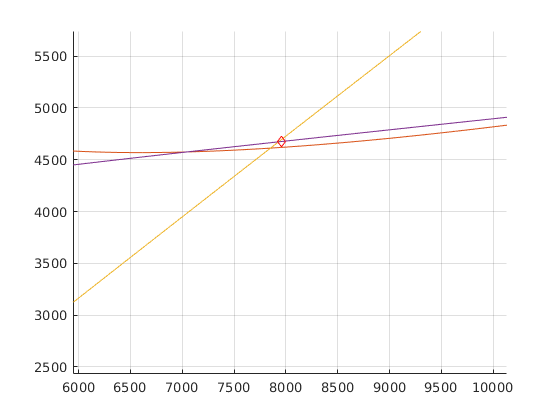


figure();
hold on;
axis equal;
plot(xapprox, yapprox, 'rx'); 
plot(d1(1,:),d1(2,:)); 
% plot(d2(1,:), d2(2,:)); 
plot(d3(1,:), d3(2,:)); 
plot(d4(1,:),d4(2,:));
plot(x0_init,y0_init,'rd')
grid on;
hold off;